# Parcial Realimentados 25-26

Creamos las matrices del sistema.

La relación de estados es,

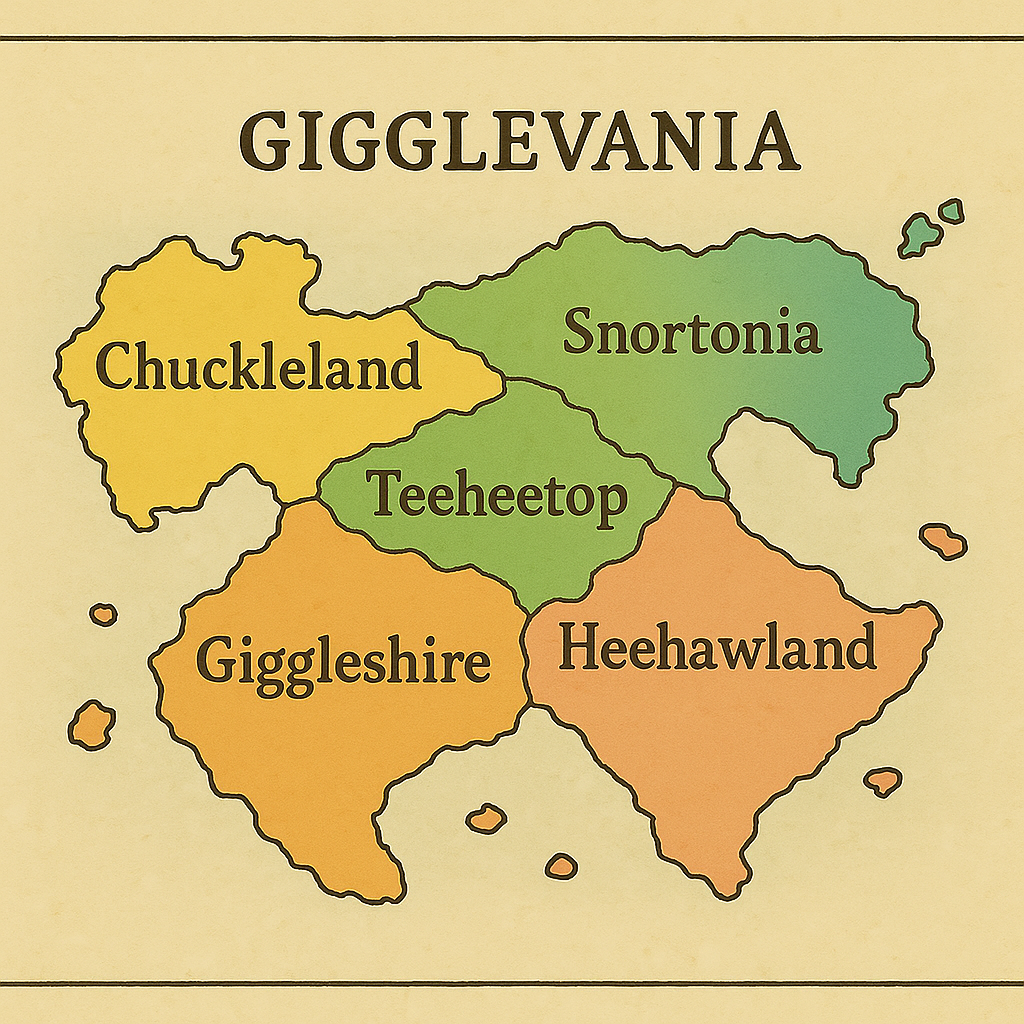

$x_1$ = Chuckeland, $x_2$ = Snortonia, $x_3$ = Teeheetop, $x_4$ = Giggleshire, $x_5$ = Heehawland

Creamos la matriz del sistema.

A = [-1 0.5 1 0 0
     0.5 -0.5 3 0 0
     1 3 -0.1 2 0
     0 0 2 -1 1
     0 0 0 1 -2]

A =    -1.0000    0.5000    1.0000         0         0
    0.5000   -0.5000    3.0000         0         0
    1.0000    3.0000   -0.1000    2.0000         0
         0         0    2.0000   -1.0000    1.0000
         0         0         0    1.0000   -2.0000


Calculamos los autovalores y autovectores de $A^T$

[v l] = eig(A')

v =    -0.1249   -0.0352    0.9270   -0.2728   -0.2224
   -0.5195   -0.3569   -0.3396   -0.4084   -0.5662
    0.6542    0.2259   -0.0688    0.0232   -0.7181
   -0.4856    0.2988    0.0857    0.7463   -0.3325
    0.2251   -0.8550    0.1154    0.4486   -0.0604


l =    -4.1578         0         0         0         0
         0   -2.3495         0         0         0
         0         0   -1.2574         0         0
         0         0         0   -0.3366         0
         0         0         0         0    3.5012


Hay un autovalor real positivo, por tanto el sistema no es estable (Los autovalores de $A^T$ y los de $A$ son iguales.

Cremos la matriz de las entradas,

B =[1 2 0 0 0; 1 0 1 0 0; 1 0 0 0 0; 1 0 0 2 0; 1 0 0 0 5]

B =      1     2     0     0     0
     1     0     1     0     0
     1     0     0     0     0
     1     0     0     2     0
     1     0     0     0     5


Y también la matriz de las salidas

C = [1 1 0 0 0;0 0 0 1 1]

C =      1     1     0     0     0
     0     0     0     1     1


Comporbamos la controlabilidad mirando el rango de la matriz de controlabilidad,

rank(ctrb(A,B))

ans = 5

Vamos a pasar el test de autovalores, para hacernos una idea de los que podemos o no quitar

Para $B$ original,

B'*v

ans =    -0.2508   -0.7223    0.7198    0.5369   -1.8997
   -0.2498   -0.0703    1.8539   -0.5456   -0.4449
   -0.5195   -0.3569   -0.3396   -0.4084   -0.5662
   -0.9713    0.5977    0.1715    1.4926   -0.6650
    1.1253   -4.2752    0.5772    2.2432   -0.3022


Nos da el  resultado conocido, no hay ningún autovector de $A^T$ en el kernel de $B^T$ por tanto el sistema es comprobable

Probamos que pasa si solo se controla la lluvia

Bll = [1 0 0 0 0; 1 0 0 0 0; 1 0 0 0 0; 1 0 0 0 0; 1 0 0 0 0]

Bll =      1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0


Bll'*v

ans =    -0.2508   -0.7223    0.7198    0.5369   -1.8997
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


Tampoco en este caso tenemos autovectores en el kernel el sistema sigue siendo controlable.

Probamos si solo se controla la influencia al último estado Heehawland $x_5$ = Heehawland

BHee = zeros(5,5);
BHee(5,5) = B(5,5) 

BHee =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     5


BHee'*v

ans =          0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
    1.1253   -4.2752    0.5772    2.2432   -0.3022


Tampoco hay autovectores en el kernel, así que es controlable tanbien

Estudiamos ahora la observabilidad

rank(obsv(A,C))

ans = 5

Como sale fullrank el sistema es observable

Estudiamos la evolución sin control.(Funciones al final del script.)

u =zeros(5,1);

Crreamos un handle a la función que describe el sistema de modo que fije A, B y U y solo dependa de t y x. Imponemos las condiciones iniales prescritas, 

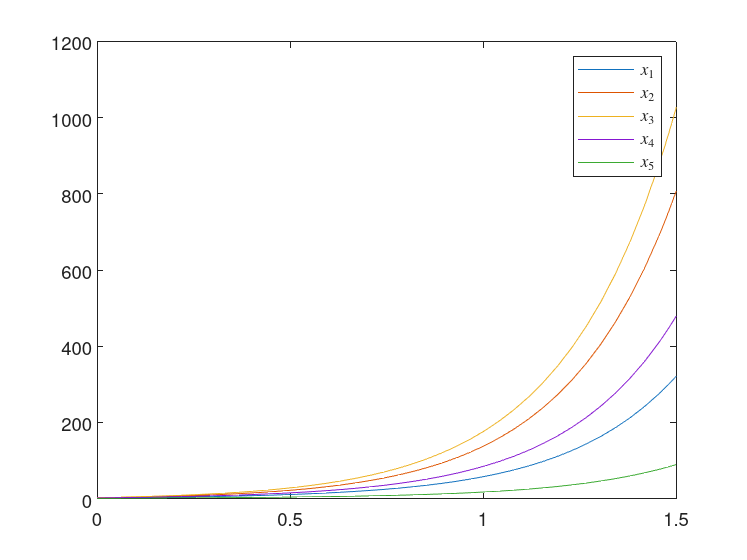

sys = @(t,x)lanzas(t,x,A,B,u);
x0 = [1;3;3;2;1];
tf = 1.5;
%opciones = odeset('maxstep',1e-5);
[t,x] = ode45(sys,[0,tf],x0);%,opciones);
figure(1)
plot(t,x)
legend({'$x_1$','$x_2$','$x_3$','$x_4$','$x_5$'},'Interpreter', 'latex' )

Efectivamente el sistema es inestable y vamos a la guerra.

Desarme por realimentación de estados con todos los polos a la izquierda de -5 (colocados empleando el método de Lyapunov),

mu = 5;
W = lyap(-mu*eye(5)-A,B*B')

W =     0.6269    0.1041   -0.0596    0.1570    0.0708
    0.1041    0.3354   -0.1872    0.2826   -0.0600
   -0.0596   -0.1872    0.3712   -0.3488    0.3774
    0.1570    0.2826   -0.3488    0.9898   -0.7617
    0.0708   -0.0600    0.3774   -0.7617    4.5872


Comprobamos que W sale definida positiva,

eig(W)

ans =     0.1526
    0.2601
    0.5491
    1.1586
    4.7900


Calculamos la ganancia de realimentación

K = B'*W^-1/2

K =     0.4749    2.5393    3.6279    0.9829   -0.0004
    1.7194   -0.3868   -0.0780   -0.2398   -0.0650
   -0.1934    2.3785    0.8832   -0.4206   -0.1084
   -0.2398   -0.8412    1.0267    1.8111    0.2089
   -0.1625   -0.5420   -0.4870    0.5224    0.6672


Usamos una función in-line para definir la entrada realimentada. Esto se puede modelar de muchas formas. (Ver función del sistema definida al final del script)

u =@(x)-K*x

u = function_handle with value:
    @(x)-K*x


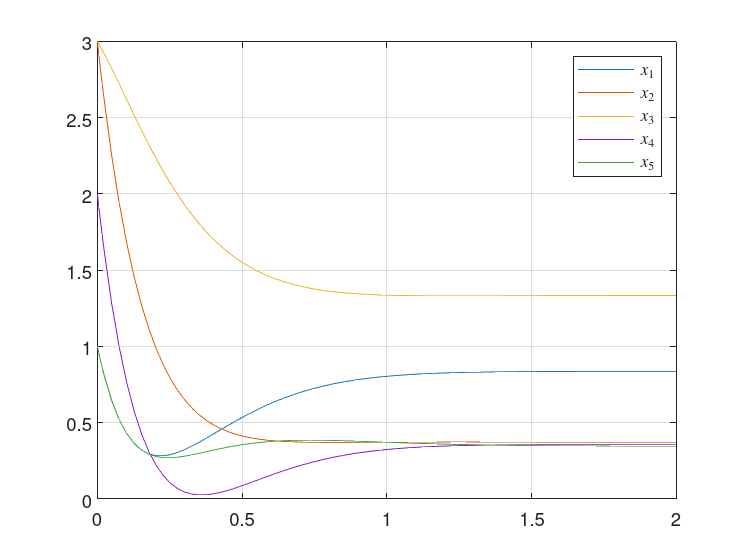

sys = @(t,x)paz(t,x,A,B,u);
x0 = [1;3;3;2;1];
tf = 2;
%opciones = odeset('maxstep',1e-5);
[t,x] = ode45(sys,[0,tf],x0);%,opciones);
figure(2)
plot(t,x)
grid
legend({'$x_1$','$x_2$','$x_3$','$x_4$','$x_5$'},'Interpreter', 'latex' )

Construimos un estimador de estados

Para ello, usamos place para colocar los autovalores en los lugares sugeridos

%L = place(A',C',[-5,-5,-4,-4,-3])'
L = place(A',C',[-2,-2,-3,-3,-1])'

L =     0.3793    1.8195
    0.6030    4.9051
    2.1394    4.8041
   -0.4553    4.4177
   -0.0000    1.0000


Cosntruimos una matriz amplida que reune el sistema y su estimador. Similamos (Ver función del sistema al final del script).

Amp = [A -B*K;
L*C A-B*K-L*C]

Amp =    -1.0000    0.5000    1.0000         0         0   -3.9136   -1.7657   -3.4719   -0.5033    0.1304
    0.5000   -0.5000    3.0000         0         0   -0.2815   -4.9177   -4.5111   -0.5623    0.1088
    1.0000    3.0000   -0.1000    2.0000         0   -0.4749   -2.5393   -3.6279   -0.9829    0.0004
         0         0    2.0000   -1.0000    1.0000    0.0046   -0.8568   -5.6814   -4.6051   -0.4175
         0         0         0    1.0000   -2.0000    0.3375    0.1706   -1.1931   -3.5947   -3.3357
    0.3793    0.3793         0    1.8195    1.8195   -5.2930   -1.6451   -2.4719   -2.3229   -1.6891
    0.6030    0.6030         0    4.9051    4.9051   -0.3845   -6.0207   -1.5111   -5.4674   -4.7964
    2.1394    2.1394         0    4.8041    4.8041   -1.6143   -1.6787   -3.7279   -3.7870   -4.8037
   -0.4553   -0.4553         0    4.4177    4.4177    0.4600   -0.4015   -3.6814  -10.0227   -3.8352
   -0.0000   -0.0000         0    1.0000    1.0000    0.3375    0.1706   -1.1931   -3

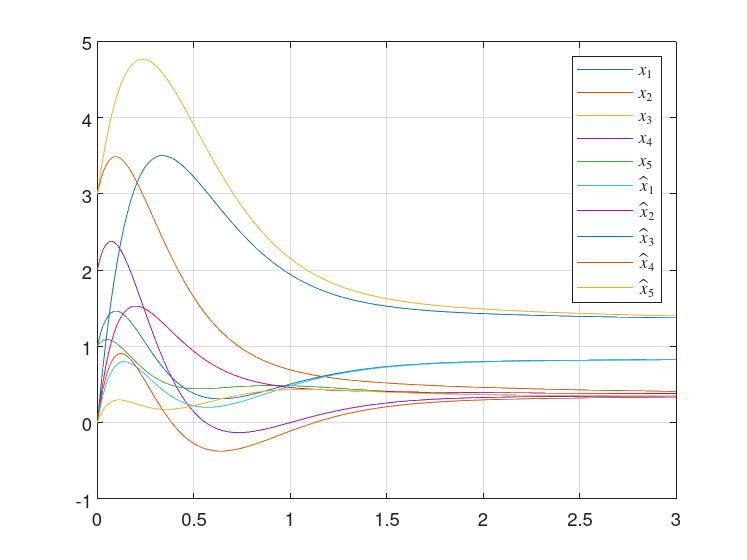

sys = @(t,x)lanzasest(t,x,Amp);
tf = 3;
x0 = [1;3;3;2;1;0;0;0;0;0];
%opciones = odeset('maxstep',1e-5);
[t,x] = ode45(sys,[0,tf],x0);%,opciones);
figure(3)
plot(t,x)
grid
legend({'$x_1$','$x_2$','$x_3$','$x_4$','$x_5$',...
    '$\hat x_1$','$\hat x_2$','$\hat x_3$','$\hat x_4$','$\hat x_5$'},'Interpreter', 'latex' )

Lo simulamos como un sistema autónomo. Bien, pero es evidente que se siguen produciendo lanzas una vez que se llega a la estabilidad.

Añadimos control integral para llegar al desarme mundial

probamos si es posible.Para ello construimos las ampliadas,

Aint = [A zeros(size(A));eye(size(A)) zeros(size(A))]

Aint =    -1.0000    0.5000    1.0000         0         0         0         0         0         0         0
    0.5000   -0.5000    3.0000         0         0         0         0         0         0         0
    1.0000    3.0000   -0.1000    2.0000         0         0         0         0         0         0
         0         0    2.0000   -1.0000    1.0000         0         0         0         0         0
         0         0         0    1.0000   -2.0000         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0         0         0
         0         0    1.0000         0         0         0         0         0         0         0
         0         0         0    1.0000         0         0         0         0         0         0
         0         0         0         0    1.0000         0         0         0    

Bint=[B; zeros(size(B))]

Bint =      1     2     0     0     0
     1     0     1     0     0
     1     0     0     0     0
     1     0     0     2     0
     1     0     0     0     5
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


Comporbamos que son controlables,

rank(ctrb(Aint,Bint))

ans = 10

Es controlable la ampliada, podemos salvar la isla de su destrucción final

necesitamos recalcular los polos para incluir el integrador vamos a usar place. ponemos los polos del sistema cerca de donde los calculamos y los del integrador a su izquierda,

Kt = place(Aint,Bint,[-5,-5,-5,-5,-5,-10,-10,-10,-10,-10])

Kt =     1.0000    3.0000   14.9000    2.0000   -0.0000   -0.0000   -0.0000   50.0000   -0.0000   -0.0000
    6.5000   -1.2500   -6.9500   -1.0000    0.0000   25.0000    0.0000  -25.0000    0.0000    0.0000
   -0.5000   11.5000  -11.9000   -2.0000    0.0000   -0.0000   50.0000  -50.0000    0.0000    0.0000
   -0.5000   -1.5000   -6.4500    6.0000    0.5000   -0.0000    0.0000  -25.0000   25.0000    0.0000
   -0.2000   -0.6000   -2.9800   -0.2000    2.6000    0.0000   -0.0000  -10.0000    0.0000   10.0000


Separamos los polos del sistema de los del control integral.

K = Kt(:,1:5)

K =     1.0000    3.0000   14.9000    2.0000   -0.0000
    6.5000   -1.2500   -6.9500   -1.0000    0.0000
   -0.5000   11.5000  -11.9000   -2.0000    0.0000
   -0.5000   -1.5000   -6.4500    6.0000    0.5000
   -0.2000   -0.6000   -2.9800   -0.2000    2.6000


Ki = Kt(:,6:10)

Ki =    -0.0000   -0.0000   50.0000   -0.0000   -0.0000
   25.0000    0.0000  -25.0000    0.0000    0.0000
   -0.0000   50.0000  -50.0000    0.0000    0.0000
   -0.0000    0.0000  -25.0000   25.0000    0.0000
    0.0000   -0.0000  -10.0000    0.0000   10.0000


Cosntruimos la matriz completa con el integrador,

Atot =[A -B*K -B*Ki
      L*C A-B*K-L*C -B*Ki
       zeros(size(A)) eye(size(A))  zeros(size(A))]

Atot =    -1.0000    0.5000    1.0000         0         0  -14.0000   -0.5000   -1.0000    0.0000   -0.0000  -50.0000    0.0000   -0.0000    0.0000   -0.0000
    0.5000   -0.5000    3.0000         0         0   -0.5000  -14.5000   -3.0000   -0.0000   -0.0000    0.0000  -50.0000         0   -0.0000   -0.0000
    1.0000    3.0000   -0.1000    2.0000         0   -1.0000   -3.0000  -14.9000   -2.0000    0.0000    0.0000    0.0000  -50.0000    0.0000    0.0000
         0         0    2.0000   -1.0000    1.0000    0.0000    0.0000   -2.0000  -14.0000   -1.0000    0.0000    0.0000   -0.0000  -50.0000   -0.0000
         0         0         0    1.0000   -2.0000    0.0000    0.0000   -0.0000   -1.0000  -13.0000    0.0000    0.0000   -0.0000    0.0000  -50.0000
    0.3793    0.3793         0    1.8195    1.8195  -15.3793   -0.3793         0   -1.8195   -1.8195  -50.0000    0.0000   -0.0000    0.0000   -0.0000
    0.6030    0.6030         0    4.9051    4.9051   -0.6030  -15.6030         0   -4.9

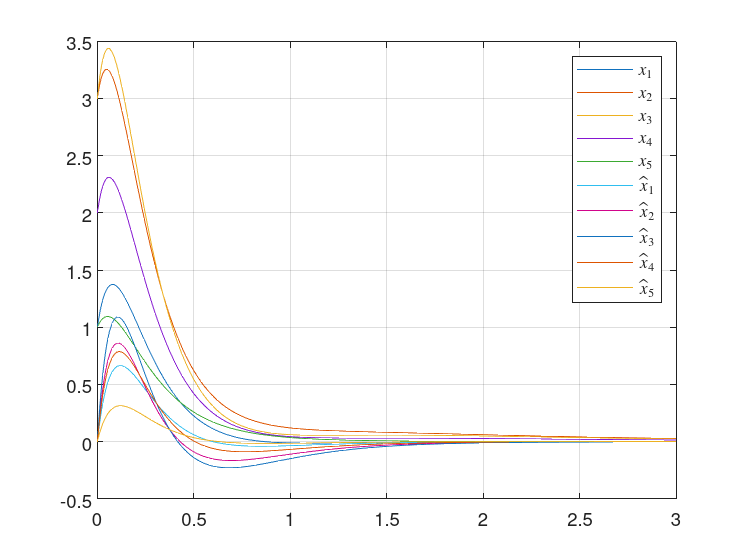

yd = zeros(15,1);
sys = @(t,x)intlanza(t,x,Atot,yd);
tf = 3;
x0 = [1;3;3;2;1;0;0;0;0;0;0;0;0;0;0];
%opciones = odeset('maxstep',1e-5);
[t,x] = ode45(sys,[0,tf],x0);%,opciones);
figure(3)
plot(t,x(:,1:10))
grid
legend({'$x_1$','$x_2$','$x_3$','$x_4$','$x_5$',...
    '$\hat x_1$','$\hat x_2$','$\hat x_3$','$\hat x_4$','$\hat x_5$'},'Interpreter', 'latex' )

El mundo es ahora un lugar mejor ;)

function xdot = lanzas(t,x,A,B,u)
%Se puede hacer de varias maneras, pero esta es la función general
%
xdot = A*x +B*u+[8,4,4,7,4]';
end
function xdot = paz(t,x,A,B,u)
xdot = A*x +B*u(x)+[8,4,4,7,4]';
end
function xdot = lanzasest(t,x,A)
xdot = A*x+[8,4,4,7,4,8,4,4,7,4]';
end
function xdot = intlanza(t,x,A,yd)
xdot = A*x +yd+[8,4,4,7,4,8,4,4,7,4,0,0,0,0,0]';
end